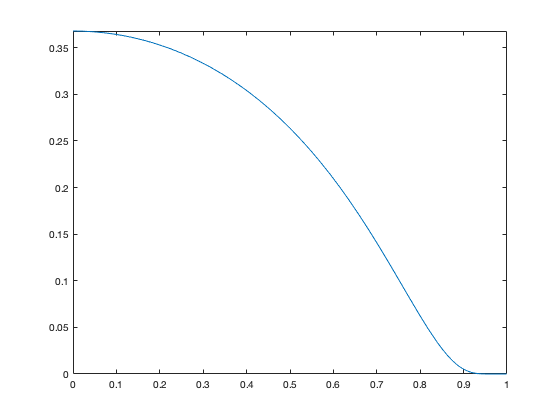

clc; clear;

f = @(x) exp(1./(x.^2-1));

C = 27;
d = 4;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

figure;
fplot(f, [0, 1])


h = 0.01;
n = 4;

fcont = fcont_gram_blend_S(f(linspace(0, n*h, n)'), d, A, Q)

fcont =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0008
    0.0037


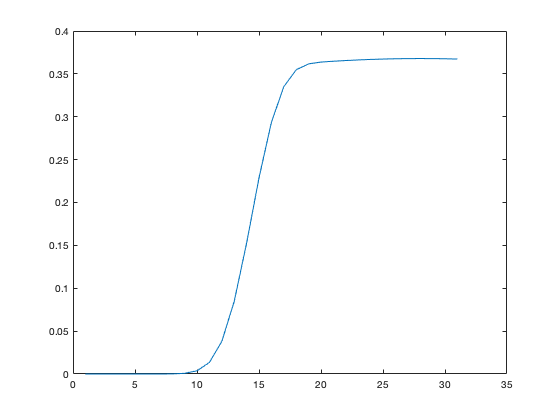


plot(fcont)